# To test different models for lattice characterization

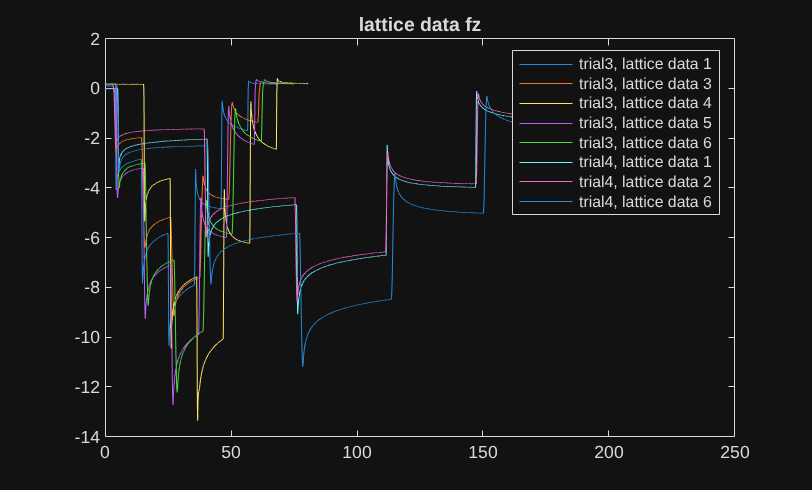

index_4 = ['1';'2';'6']; % for trial4
index_3 = ['1';'3';'4';'5';'6']; % for trial3
folder_4 = "lattice_calibration_data/15x15x15/trial4/";
folder_3 = "lattice_calibration_data/15x15x15/trial3/";

figure;
for i=1:size(index_3,1)
    filename = folder_3 + "lattice_data_" + index_3(i) + ".mat";
    load(filename);
    plot(t_biased,fz);
    
    hold on;
end

for i=1:size(index_4,1)
    filename = folder_4 + "lattice_data_" + index_4(i) + ".mat";
    load(filename)
    plot(t_biased,fz);
    hold on;
end

title("lattice data fz");
legend(["trial3, lattice data "+index_3 ; "trial4, lattice data "+index_4]);
hold off;

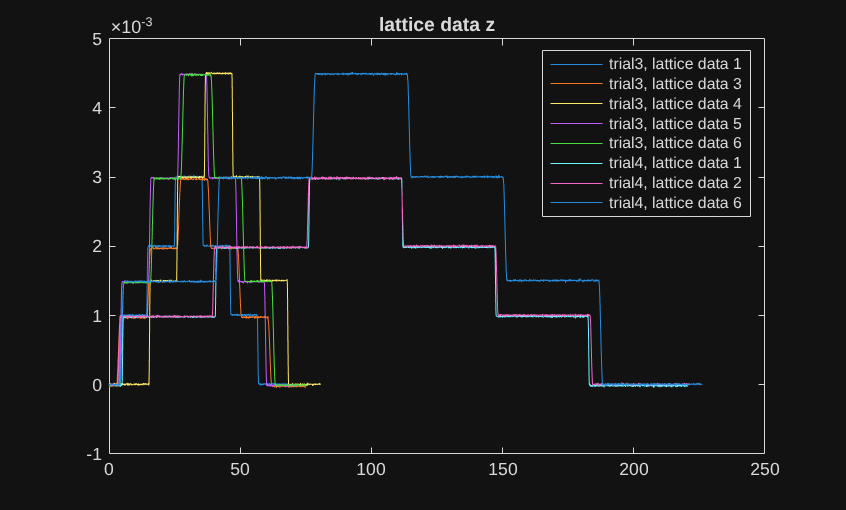


figure
for i=1:size(index_3,1)
    filename = folder_3 + "lattice_data_" + index_3(i) + ".mat";
    load(filename);
    plot(t_biased,z);
    hold on;
end

for i=1:size(index_4,1)
    filename = folder_4 + "lattice_data_" + index_4(i) + ".mat";
    load(filename);
    plot(t_biased, z);
    hold on;
end

title("lattice data z");
legend(["trial3, lattice data "+index_3; "trial4, lattice data "+index_4]);
hold off;